## Theory

In Alexander et al. paper, the DT (diffusion tensor) should be changes when the DT images transformed to another space with rotation matrix R as follows:


$$\[{D^'} = RD{R^T}\]$$


It can be infered by original signal reduction equation:


$$\[\begin{array}{l}
{S_i} = {S_0} * \exp \left( { - b_i^TD{b_i}} \right)\\
{S_i} = {S_0} * \exp \left( { - {{(R{b_i})}^T}{D^'}(R{b_i})} \right)
\end{array}\]$$


From this equation, we believe rotating the DT is same to rotating the magnetic fields (bi).

## Validataion

- experiment 1

 It is straightforward to verify our guess, for they coming from the same equation. We use the following code to run this experiment.

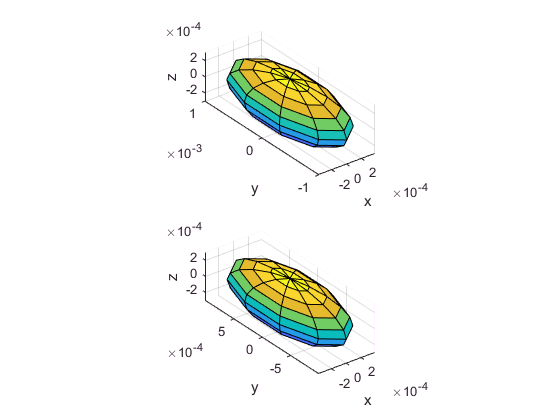

% Diffusion gradient directions
bvec = load(spm_select(1, 'grad', 'bvec'));
bval = load(spm_select(1, 'bval', 'bval'));
b_matrix = bval_bvec_to_matrix(bval', bvec);

% Simulated DWI signals
S0 = 500;
DT0 = diag([1, 0.3, 0.4])*1e-3;
RotVec = pi/2*[0, 0, 1];
RotMat = rotationVectorToMatrix(RotVec);
DT1 = RotMat*DT0*RotMat'
[el_x1, el_y1, el_z1, rot_axis1, rot_angle1] = plot_ellipsoid(DT1);

y_exp = S0*exp(-b_matrix*[DT0(1, 1:3), DT0(2, 2:3), DT0(3, 3)]');
bvec_rot = RotMat*bvec;
b_matrix_rot = bval_bvec_to_matrix(bval', bvec_rot);
DT2_vec = estimate_DT_with_RESTORE(b_matrix_rot, y_exp);
DT2 = ones(3, 3);
DT2(tril(DT2) > 0) = DT2_vec;
DT2 = tril(DT2) + triu(DT2', 1)
[el_x2, el_y2, el_z2, rot_axis2, rot_angle2] = plot_ellipsoid(DT2);
% Plotting
subplot(2, 1, 1)
rotate(surf(el_x1, el_y1, el_z1), rot_axis1, rot_angle1);
xlabel('x'), ylabel('y'), zlabel('z');
axis equal
subplot(2, 1, 2)
rotate(surf(el_x2, el_y2, el_z2), rot_axis2, rot_angle2);
xlabel('x'), ylabel('y'), zlabel('z');
axis equal